This livescript support the interpreation of the anticipation results.

The anticipation and pain phases wre contrasted separately for the placebo and control condition and for them together as well. We normally would end up with one image per contrast, but as we need to run pTFCE (which can only be used on positive values) always deal with two images. However, the sign differs only in these images.

intermedpath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles'; 
load(fullfile(intermedpath,'data_frame'),'df');
% load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent_equalmask.mat')
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\both\both_diff_g_rnd_neg_ptfce.nii.gz'

img = 'C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\both\both_diff_g_rnd_neg_ptfce.nii.gz'

thresholdfrommaxstat=max(vectorizedimg_masked);%4.42%this is the one sided, while 4.62 is the twosided previous run.this is a bit different, not sure why exactly...
vectorizedimg=v_masked_BK(img);

Compressed NIfTI files are not supported.


vectorizedimg_masked=vectorizedimg(dfv_masked.both_brainmask);
signifmask=vectorizedimg_masked>=thresholdfrommaxstat;
sum(signifmask)

ans = 1

activity=[];
counter=1;
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1})
%         activity.antplac(counter)=avgnormalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask));
%         activity.antcontr(counter)=avgnormalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask));
%         activity.painplac(counter)=avgnormalize(dfv_masked.pain_placebo{studyrank,1}(:,signifmask));
%         activity.paincontr(counter)=avgnormalize(dfv_masked.pain_control{studyrank,1}(:,signifmask));

%         anticip-pain raw difference for placebo and control separately was introduced to the summarize_within
%         function. Therefore only the correlation between the two conditions,
%         placebo and control, was used in the summary stat.


        activity.antplac(counter)=summarize_within_BK(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask),0);
        activity.antcontr(counter)=summarize_within_BK(dfv_masked.anticip_control{studyrank,1}(:,signifmask),0);
        activity.painplac(counter)=summarize_within_BK(dfv_masked.pain_placebo{studyrank,1}(:,signifmask),0);
        activity.paincontr(counter)=summarize_within_BK(dfv_masked.pain_control{studyrank,1}(:,signifmask),0);
        activity.studynm(counter)=df.study_ID(studyrank);
        counter=counter+1;
    end


end
%todo use the code snippet below to find clusters in the data, first one
%need to get rid off the Na values(see also the script for visualization)
% minSeparation = 200;
% nonZeroElements = ~bwareaopen(~dfv_masked.anticip_brainmask3d, minSeparation);
% [labeledRegions, numRegions] = bwlabel(nonZeroElements);

% Sample struct
% data_struct.antplac= activity.antplac;
% data_struct.antcontr=activity.antcontr;
% data_struct.painplac=activity.painplac;
% data_struct.paincontr=activity.paincontr;

data_struct.antplac=horzcat(activity.antplac(:).g);
data_struct.antcontr=horzcat(activity.antcontr(:).g);
data_struct.painplac=horzcat(activity.painplac(:).g);
data_struct.paincontr=horzcat(activity.paincontr(:).g);
data_struct.name = activity.studynm;


% Convert struct fields into cell arrays
name_cell = data_struct.name';
ap_cell= num2cell(data_struct.antplac');
ac_cell=num2cell(data_struct.antcontr');
pp_cell=num2cell(data_struct.painplac');
pc_cell=num2cell(data_struct.paincontr');

% Combine cell arrays into a single cell array
combined_cell = [name_cell, ap_cell, ac_cell,pp_cell,pc_cell];

% Specify the file name
file_name = 'C:\Users\lenov\Documents\PICO\C_calculations\D_results\interactioninterpret\studywiseavgeffectsizesunderthesignmaskofinteractioneff_g_0r.csv';
% Convert cell array to a table
T = cell2table(combined_cell, 'VariableNames', {'studyid', 'anticip_placebo',   'anticip_control', 'pain_placebo','pain_control'});

% Write table to a CSV file
writetable(T, file_name);



Visualize the average Cohen's d value for each individual studies from each phase and condition

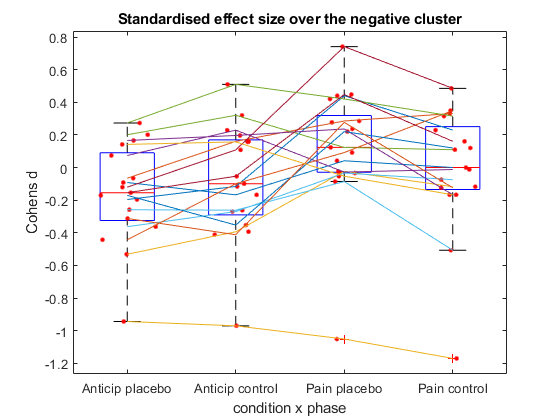

data = [activity.antplac', activity.antcontr',  activity.painplac',activity.paincontr'];
figure()
% Create a boxplot
boxplot(data, 'Labels', {'Anticip placebo',  'Anticip control', 'Pain placebo','Pain control'});
title('Standardised effect size over the negative cluster');
xlabel('condition x phase');
ylabel('Cohens d');
hold on;  % Allow multiple plots on the same axes

% Plot individual data points as an overlay
numGroups = size(data, 2);
for i = 1:numGroups
    x = i + randn(size(data, 1), 1) * 0.1;  % Add jitter for visibility
    plot(x, data(:, i), 'r.', 'MarkerSize', 10);
end
numGroups = size(data, 1);
colors = colormap(lines(numGroups));
for i = 1:size(data, 1)
    lineColors = colors(i, :);
    plot([1, 2, 3 ,4], [data(i, 1), data(i, 2),data(i, 3),data(i, 4)], '-','Color', lineColors);  % Connect Group 1 and Group 2
end

hold off;

hold off

mean(data)

ans =    -0.1640   -0.0828    0.1210   -0.0136


Here I try to help the interpretation of the results coming from only the anticipation phase (contrast, sum, and correlation).

vectorizedimgdatapath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\vectorized_images_full_masked_10_percent.mat';
load(vectorizedimgdatapath)
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_g_rnd_neg.nii';
% % img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_neg_ptfce.nii.gz';
% vectorized_img=v_masked_BK(img);
% fwerthrshold.corr=4.62;
% fwerthrshold.diff=4.7;
% % signifvox=vectorized_img>fwerthrshold.corr;
% signifvox=vectorized_img>fwerthrshold.diff;
% signifmask_masked=signifvox(dfv_masked.anticip_brainmask);


This is the significant cluters in the difference analysis:

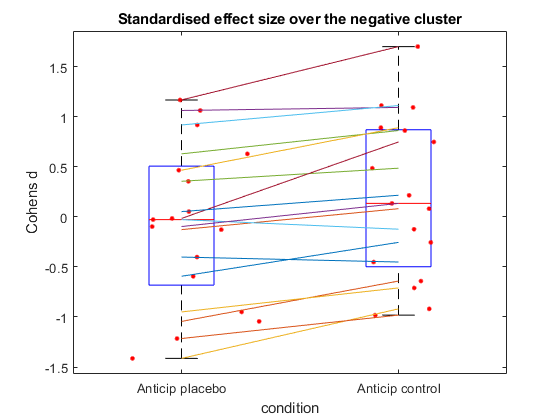

img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_g_rnd_neg.nii';
vectorized_img=v_masked_BK(img);
thrshold.diff=4.7;
signifvox=vectorized_img>thrshold.diff;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

activity=[];
counter=1;
for studyrank=1:height(df)
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1})
        activity.antplac(counter)=avgnormalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked));
        activity.antcontr(counter)=avgnormalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked));
        
        activity.studynm(counter)=df.study_ID(studyrank);
        counter=counter+1;
    end


end
data = [activity.antplac', activity.antcontr'];
figure()
% Create a boxplot
boxplot(data, 'Labels', {'Anticip placebo',  'Anticip control'});
title('Standardised effect size over the negative cluster');
xlabel('condition');
ylabel('Cohens d');
hold on;  % Allow multiple plots on the same axes

% Plot individual data points as an overlay
numGroups = size(data, 2);
for i = 1:numGroups
    x = i + randn(size(data, 1), 1) * 0.1;  % Add jitter for visibility
    plot(x, data(:, i), 'r.', 'MarkerSize', 10);
end
numGroups = size(data, 1);
colors = colormap(lines(numGroups));
for i = 1:size(data, 1)
    lineColors = colors(i, :);
    plot([1, 2], [data(i, 1), data(i, 2)], '-','Color', lineColors);  % Connect Group 1 and Group 2
end

hold off;

This is the significant cluster in the correlation analysis:

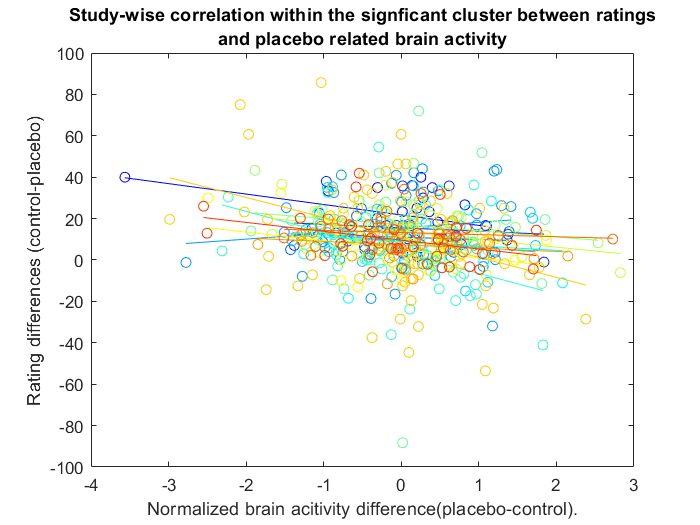

i=1;

img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
%  figure()
h = figure;
inludedstudies=[];
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
        ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
        ratings=-df.GIV_stats_rating101(studyrank).delta;
        normbrainact=normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)- ...
            dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end
%lgd=legend(df.study_ID(inludedstudies),'Location','eastoutside');

% chleg = get(lgd,'children');
% for maki=1:length(inludedstudies)
%     set(chleg(maki),'color',cmap(maki,:))
% end
%lgd.FontSize=6;
%lgd.NumColumns = 2;
title({'Study-wise correlation within the signficant cluster between ratings' 'and placebo related brain activity'})
xlabel('Normalized brain acitivity difference(placebo-control).') 
ylabel('Rating differences (control-placebo)')
hold off
print(h,'correlationinputamen','-dpdf','-r0')

Indiviudal studies correlation.

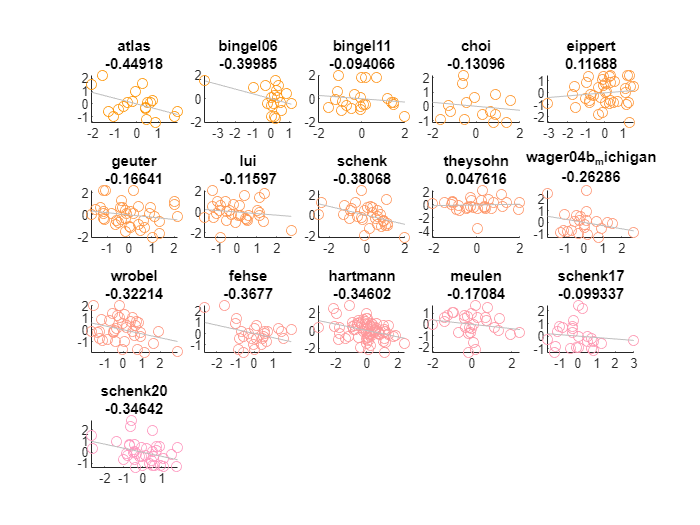


i=1;
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);
allratingsnorm=[];
allbrainactivitynorm=[];
for studyrank=1:height(df) %stats
    
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design(studyrank),'within') % necessary as "sum" returns 0 for [] for some stupid reason
        % with this condition we should only exclude between subject studies (2of them)
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        %scatter(h(i),mean(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'),-df.GIV_stats_rating101(studyrank).delta)
        ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
        ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
        ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');

        brainacitvity=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)-...
            dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked),2,'omitnan');
        brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');

%         allratingsnorm=vertcat(allratingsnorm,ratingsnormalized);
%         allbrainactivitynorm=vertcat(allbrainactivitynorm,brainacitvitynormalized);
%         scatter(brainacitvitynormalized,ratings,[],RGB)
        scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        
        maki=dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked)-dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked);
        coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'));
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
%         calccorr=fastcorrcoef_BK(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),-df.GIV_stats_rating101(studyrank).delta,'exclude_nan');
%         fprintf("previously calculated correlation in %s study:%f\n",df.study_ID{studyrank},mean(placebo_stats(studyrank).r_external(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'))
%         fprintf("newly calculated correlation in %s study:%f\n",df.study_ID{studyrank},mean(calccorr,'omitnan'))
        h(i)=lsline;
        
%         set(h(i),'color','r')
        
%         coracrossvoxels=-mean(placebo_stats(studyrank).r_external(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan');
%         title(h(i), text([df.study_ID{studyrank}+"-study"+string(coracrossvoxels)]))
%         hold on
%         activity=placebo_stats(studyrank).delta; %this is also placebo-control delta, as it was specified in this order above in the summary_within arguments.
%         ratings=df.GIV_stats_rating(studyrank).delta(~ex_subj,:); %this is placebo-control delta, as it was the order in the summary_within arguments.
%         placebo_stats(studyrank).r_external=fastcorrcoef_BK(activity,ratings,'exclude_nan'); % correlate single-subject effect of behavior and voxel signal 
%         placebo_stats(studyrank).n_r_external=sum(~(isnan(activity)|... % the n for the correlation is the n of subjects showing non-nan values at that particular voxels
%                                              isnan(ratings))); % AND non nan-ratings
%     else
%         stats(studyrank).r_external=[];%NaN(1,n_voxel);
%         stats(studyrank).n_r_external=[];%NaN(1,n_voxel);
    
    i=i+1;
    end
    
    
end


i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_placeboactcorrwithbehavplaceboeff\anticip_diff_r_plaimg_pladiffbehav_rnd_pos.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
 figure()

inludedstudies=[];
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
%         ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
        ratings=-df.GIV_stats_rating101(studyrank).delta;
        normbrainact=normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end

title({'Study-wise correlation within the signficant cluster between ratings' 'and placebo brain activity'})
xlabel('Normalized brain acitivity in placebo.') 
ylabel('Rating differences (control-placebo)')
disp("This is the correlation between placebo activity and behavior analgesia ")

This is the correlation between placebo activity and behavior analgesia 


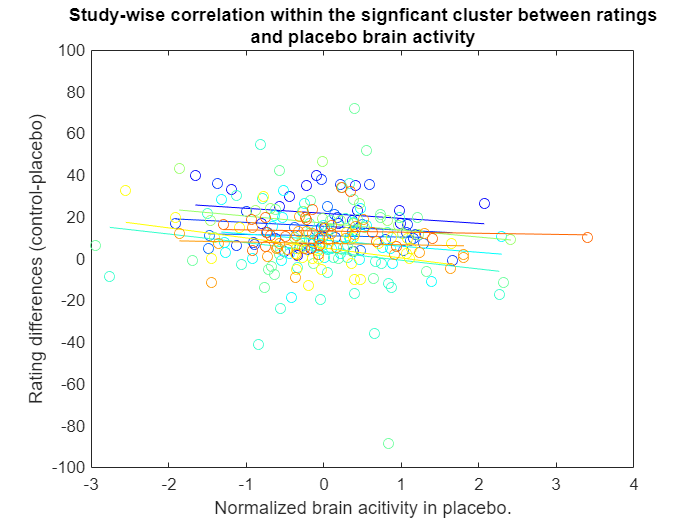

hold off

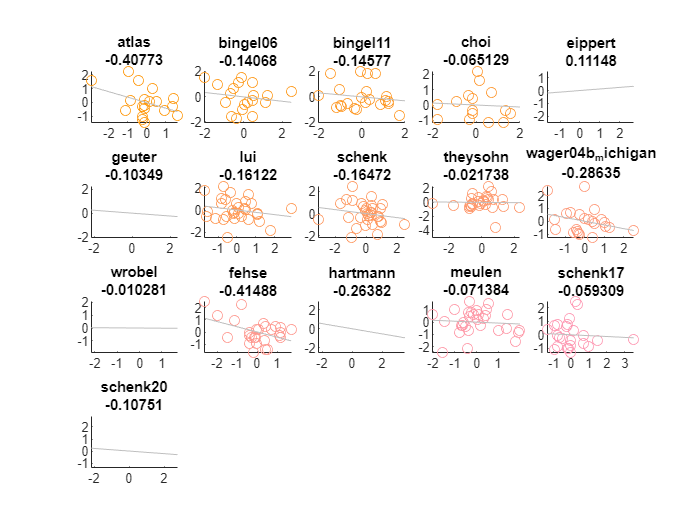


i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_placeboactcorrwithbehavplaceboeff\anticip_diff_r_plaimg_pladiffbehav_rnd_pos.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);
allratingsnorm=[];
allbrainactivitynorm=[];
for studyrank=1:height(df) %stats
    nym=[];
    
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design(studyrank),'within') % necessary as "sum" returns 0 for [] for some stupid reason
        % with this condition we should only exclude between subject studies (2of them)
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        %scatter(h(i),mean(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'),-df.GIV_stats_rating101(studyrank).delta)
        ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
        ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
        ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');

        brainacitvity=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked),2,'omitnan');
        brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');
        scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        
        maki=dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked);
        for blod=1:size(maki,2); nym(blod)=corr(maki(:,blod),ratingsnormalized,'rows','complete'); end
        coracrossvoxels=mean(nym,'omitnan');
%         coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'),'omitnan');
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
        h(i)=lsline;
%         xlabel('Normalized brain acitivity in placebo.')

    i=i+1;
    end
    
    
end
hold off

i=1;


% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_controlactcorrwithbehavplaceboeff\anticip_diff_r_contrimg_pladiffbehav_rnd_neg.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
 figure()

inludedstudies=[];
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
%         ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
        ratings=-df.GIV_stats_rating101(studyrank).delta;
        normbrainact=normalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end

title({'Study-wise correlation within the signficant cluster between ratings' 'and control brain activity'})
xlabel('Normalized brain acitivity in control.') 
ylabel('Rating differences (control-placebo)')
disp("This is the correlation between control activity and behavior analgesia ")

This is the correlation between control activity and behavior analgesia 


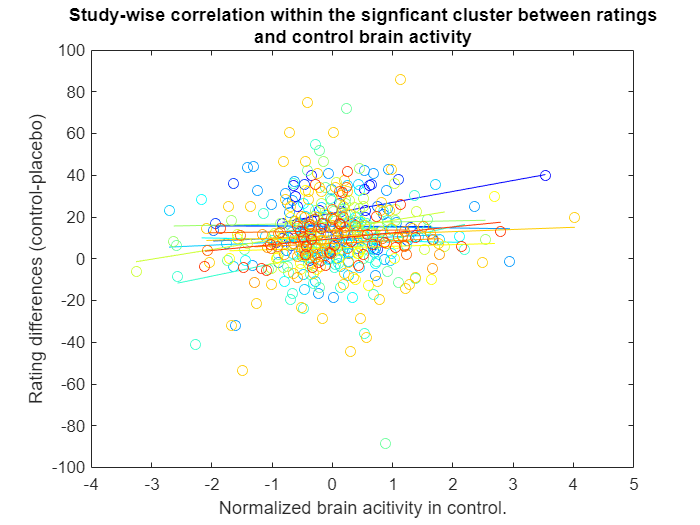

hold off

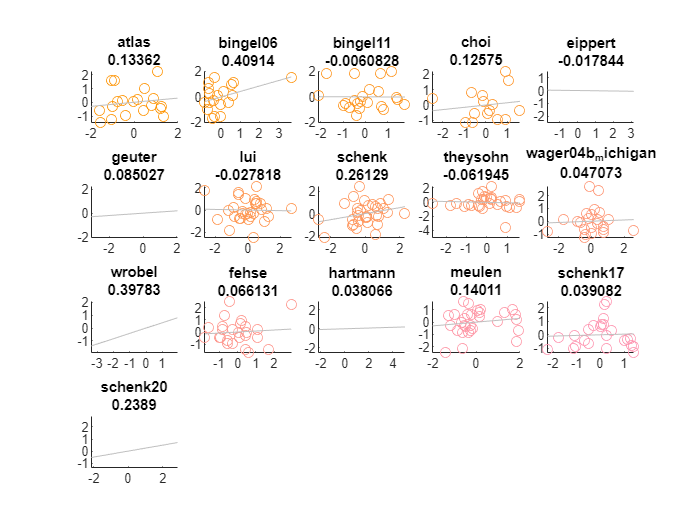

i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_controlactcorrwithbehavplaceboeff\anticip_diff_r_contrimg_pladiffbehav_rnd_neg.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);
allratingsnorm=[];
allbrainactivitynorm=[];
for studyrank=1:height(df) %stats
    nym=[];
    
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design(studyrank),'within') % necessary as "sum" returns 0 for [] for some stupid reason
        % with this condition we should only exclude between subject studies (2of them)
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        %scatter(h(i),mean(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'),-df.GIV_stats_rating101(studyrank).delta)
        ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
        ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
        ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');

        brainacitvity=mean(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked),2,'omitnan');
        brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');
        scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        
        maki=dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked);
        for blod=1:size(maki,2); nym(blod)=corr(maki(:,blod),ratingsnormalized,'rows','complete'); end
        coracrossvoxels=mean(nym,'omitnan');
%         coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'),'omitnan');
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
        h(i)=lsline;
%         xlabel('Normalized brain acitivity in placebo.')

    i=i+1;
    end
    
    
end
hold off


i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_placeboactcorrwithbehavplaceboeff\anticip_diff_r_plaimg_pladiffbehav_rnd_pos.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
 figure()

inludedstudies=[];
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
%         ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
%         ratings=-df.GIV_stats_rating101(studyrank).delta;
        ratings=df.anticip_placebo{studyrank}.rating101;
        normbrainact=normalize(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end

title({'Study-wise correlation within the signficant cluster between ratings' 'and placebo activity'})
xlabel('Normalized brain acitivity in placebo.') 
ylabel('Normalized rating in placebo')
disp("This is the correlation between placebo activity and behavior rating ")

This is the correlation between placebo activity and behavior analgesia 


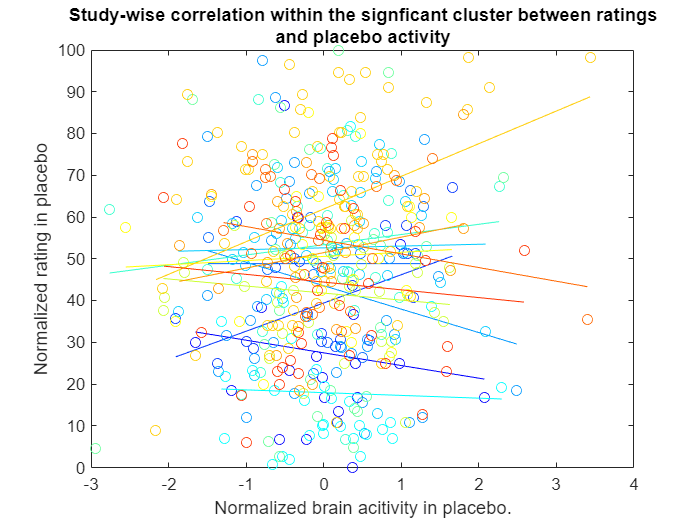

hold off

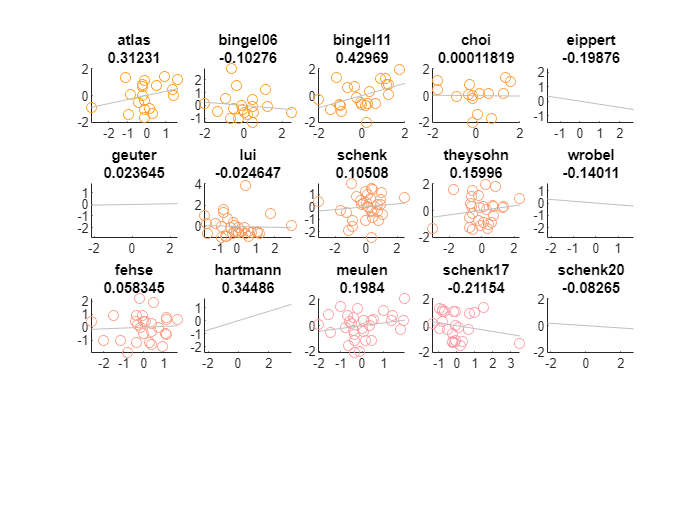


i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_placeboactcorrwithbehavplaceboeff\anticip_diff_r_plaimg_pladiffbehav_rnd_pos.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);
allratingsnorm=[];
allbrainactivitynorm=[];
for studyrank=1:height(df) %stats
    nym=[];
    
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design(studyrank),'within') && ~all(isnan(df.anticip_placebo{studyrank}.rating101)) % necessary as "sum" returns 0 for [] for some stupid reason
        % with this condition we should only exclude between subject studies (2of them)
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        %scatter(h(i),mean(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'),-df.GIV_stats_rating101(studyrank).delta)
%         ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
%         ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
        ratings=df.anticip_placebo{studyrank}.rating101;
        ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');

        brainacitvity=mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked),2,'omitnan');
        brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');
        scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        allratingsnorm=vertcat(allratingsnorm,ratingsnormalized);
        allbrainactivitynorm=vertcat(allbrainactivitynorm,brainacitvitynormalized);
        maki=dfv_masked.anticip_placebo{studyrank,1}(:,signifmask_masked);
        for blod=1:size(maki,2); nym(blod)=corr(maki(:,blod),ratingsnormalized,'rows','complete'); end
        coracrossvoxels=mean(nym,'omitnan');
%         coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'),'omitnan');
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
        h(i)=lsline;
%         xlabel('Normalized brain acitivity in placebo.')

    i=i+1;
    end
    
    
end
hold off

placsum=load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_WB_res_phasediff\WB_both_phase_plac_summary.mat');
figure()
scatter(allbrainactivitynorm,allratingsnorm);
fprintf("Correlation between pain ratings and brain acitvity in the putamen in the placebo condition: %f", corr(allbrainactivitynorm,allratingsnorm,'rows','complete'))

Correlation between pain ratings and brain acitvity in the putamen in the placebo condition: 0.026696

fprintf("Correlation value based on the GIV method:%f", mean(placsum.summaryy.r_external.random.summary(:,signifmask_masked),'omitnan'))

Correlation value based on the GIV method:-0.035336

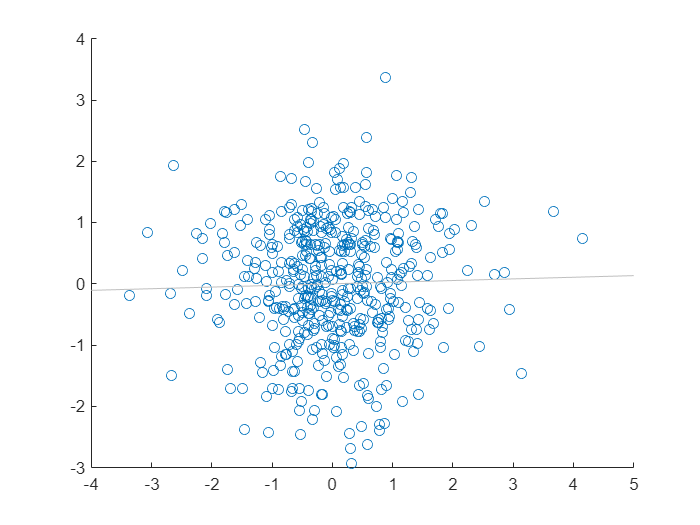

lsline

% Fit = polyfit(allbrainactivitynorm,allratingsnorm,1);

i=1;


% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_controlactcorrwithbehavplaceboeff\anticip_diff_r_contrimg_pladiffbehav_rnd_neg.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);

allratingsnorm=[];
allbrainactivitynorm=[];
 figure()

inludedstudies=[];
for studyrank=1:height(df) %stats
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && ~isempty(df.GIV_stats_rating101(studyrank).delta)
%         ratings=normalize(df.GIV_stats_rating101(studyrank).delta);
%         ratings=-df.GIV_stats_rating101(studyrank).delta;
        ratings=df.anticip_control{studyrank}.rating101;
        normbrainact=normalize(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked));
        avgnormbrainact=mean(normbrainact,2,'omitnan');
        cmap=jet(17);
        
        scatter(avgnormbrainact,ratings,[],cmap(i,:));
        Fit = polyfit(avgnormbrainact,ratings,1); % x = x data, y = y data, 1 = order of the polynomial i.e a straight line 
        plot(avgnormbrainact,polyval(Fit,avgnormbrainact),'Color',cmap(i,:))
        hold on
        i=i+1;

        inludedstudies=[inludedstudies, studyrank];


    end
  
    
end

title({'Study-wise correlation within the signficant cluster between ratings' 'and control brain activity'})
xlabel('Normalized brain acitivity in control.') 
ylabel('Rating in control')
disp("This is the correlation between control activity and behavior analgesia ")

This is the correlation between control activity and behavior analgesia 


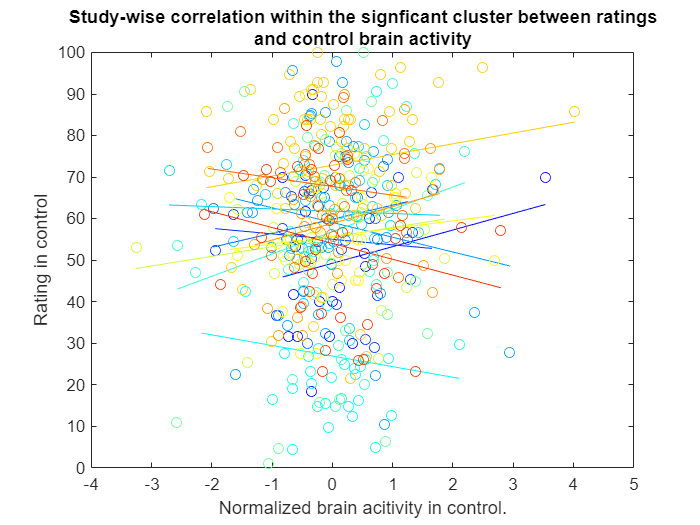

hold off

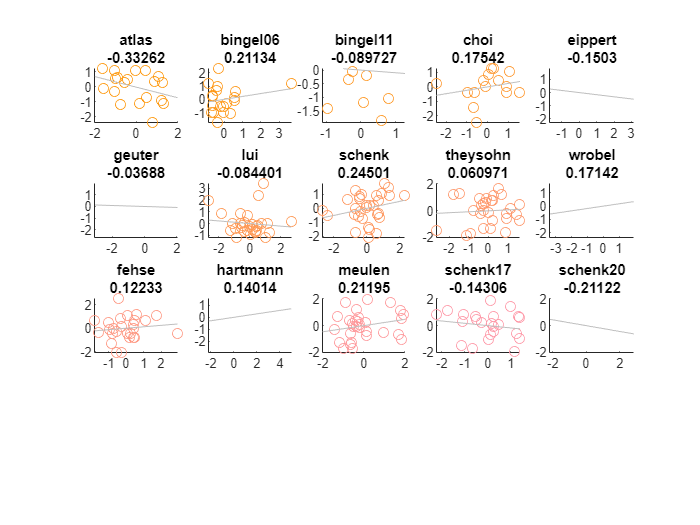

i=1;
% img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip_controlactcorrwithbehavplaceboeff\anticip_diff_r_contrimg_pladiffbehav_rnd_neg.nii';
img='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_imgs\anticip\anticip_diff_r_rnd_pos_ptfce.nii';
vectorized_img=v_masked_BK(img);
thrshold.corr=4.62;
signifvox=vectorized_img>thrshold.corr;
signifmask_masked=signifvox(dfv_masked.anticip_brainmask);
allratingsnorm=[];
allbrainactivitynorm=[];
for studyrank=1:height(df) %stats
    nym=[];
    
    if ~isempty(dfv_masked.anticip_placebo{studyrank,1}) && strcmp(df.study_design(studyrank),'within') && ~all(isnan(df.anticip_placebo{studyrank}.rating101)) % necessary as "sum" returns 0 for [] for some stupid reason
        % with this condition we should only exclude between subject studies (2of them)
        h(i)=subplot(4,5,i);
        %IMPORTANT here the sign of the behavior variable is flipped as in
        %the wholebrain paper
        RGB = [255 153 i*12]/256;
        %scatter(h(i),mean(placebo_stats(studyrank).delta(:,signifmask(dfv_masked.anticip_brainmask)),2,'omitnan'),-df.GIV_stats_rating101(studyrank).delta)
%         ratings=df.GIV_stats_rating101(studyrank).delta; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script. 
%         ratings=-ratings; %ratings originally show placebo-control(see previous row comment), and now we change so higher values mean higher placebo analgesia
        ratings=df.anticip_control{studyrank}.rating101;
        ratingsnormalized=(ratings-mean(ratings,'omitnan'))/std(ratings,'omitnan');

        brainacitvity=mean(dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked),2,'omitnan');
        brainacitvitynormalized=(brainacitvity-mean(brainacitvity,'omitnan'))/std(brainacitvity,'omitnan');
        scatter(h(i),brainacitvitynormalized,ratingsnormalized,[],RGB)
        allratingsnorm=vertcat(allratingsnorm,ratingsnormalized);
        allbrainactivitynorm=vertcat(allbrainactivitynorm,brainacitvitynormalized);
        maki=dfv_masked.anticip_control{studyrank,1}(:,signifmask_masked);
        for blod=1:size(maki,2); nym(blod)=corr(maki(:,blod),ratingsnormalized,'rows','complete'); end
        coracrossvoxels=mean(nym,'omitnan');
%         coracrossvoxels=mean(corr(maki,ratingsnormalized,'Rows','complete'),'omitnan');
        title(h(i),{df.study_ID{studyrank};string(coracrossvoxels)})
        h(i)=lsline;

%         xlabel('Normalized brain acitivity in placebo.')

    i=i+1;
    end
    
    
end
hold off

figure()
contrsumm=load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\zz_WB_res_phasediff\WB_both_phase_control_summary.mat');
scatter(allbrainactivitynorm,allratingsnorm);
fprintf("Correlation between pain ratings and brain acitvity in the putamen in the control condition: %f", corr(allbrainactivitynorm,allratingsnorm,'rows','complete'))

Correlation between pain ratings and brain acitvity in the putamen in the control condition: 0.026696

fprintf("Correlation value based on the GIV method:%f", mean(contrsumm.summaryy.r_external.random.summary(:,signifmask_masked),'omitnan'))

Correlation value based on the GIV method:-0.041019

lsline

function meancohend=avgnormalize(data)
    meancohend=mean(mean(data,'omitnan')./std(data,'omitnan'),'omitnan');
end

function cohend=normalize(data)
    cohend=(data-mean(data,'omitnan'))./std(data,'omitnan');
end

